# Adjusting Contrast

## Image Contrast Adjustment

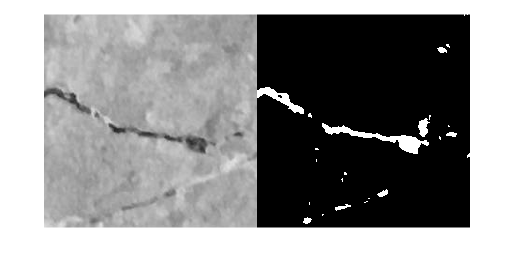

img = im2gray(imread("00035.jpg"));
BW = imbinarize(img);
BW = ~BW;
montage({img, BW})

crackPix = nnz(BW)

crackPix = 1800

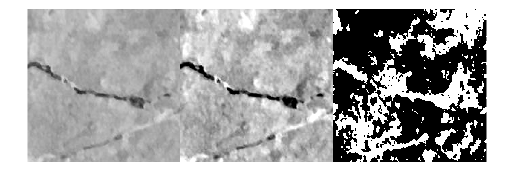

imgAdj = imadjust(img);
BWAdj = imbinarize(imgAdj);
BWAdj = ~BWAdj;
montage({img, imgAdj, BWAdj}, "Size",[1 3])

crackPixAdj = nnz(BWAdj)

crackPixAdj = 17751

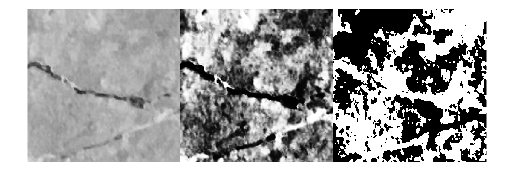

imgEq = histeq(img);
BWEq = imbinarize(imgEq);
BWEq = ~BWEq;
montage({img, imgEq, BWEq}, "Size",[1 3])

crackPixEq = nnz(BWEq)

crackPixEq = 25780

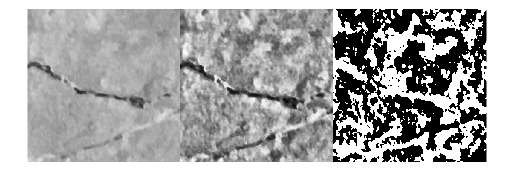

imgAdapt = adapthisteq(img);
BWAdapt = imbinarize(imgAdapt);
BWAdapt = ~BWAdapt;
montage({img, imgAdapt, BWAdapt}, "Size",[1 3])

crackPixAdapt = nnz(BWAdapt)

crackPixAdapt = 22638

## Brightening An Image

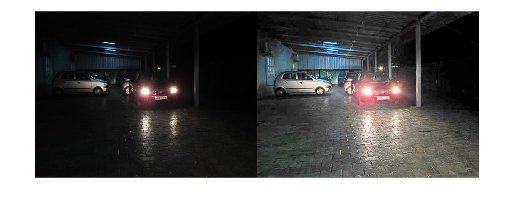

Car3 = imread("car_3.jpg");
Car3B = imlocalbrighten(Car3);
montage({Car3, Car3B})

avrLumCar3 = mean2(im2gray(Car3B)) - mean2(im2gray(Car3))

avrLumCar3 = 55.5325

## Adjusting a Single Color Plane

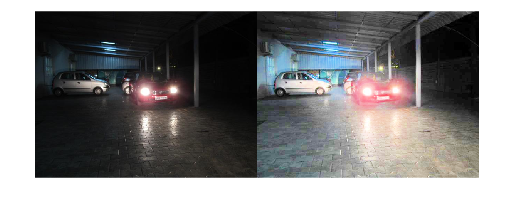

Car2rgb = imread("car_2.jpg");
Car2hsv = rgb2hsv(Car2rgb);
Car2hsv(:,:,3) = histeq(Car2hsv(:,:,3));
Car2Eq = im2uint8(hsv2rgb(Car2hsv));
montage({Car2rgb, Car2Eq})

avrLumCar2 = mean2(im2gray(Car2Eq)) - mean2(im2gray(Car2rgb))

avrLumCar2 = 82.4245

## Snow Removal

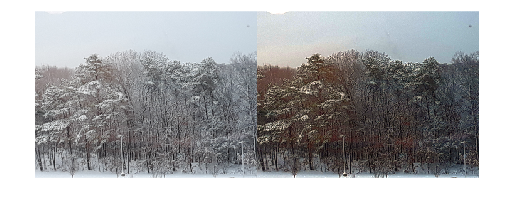

snow = imread("mountain2.jpg");
snowRemove = imreducehaze(snow);
montage({snow, snowRemove})

avrLumSnow = mean2(im2gray(snow)) - mean2(im2gray(snowRemove))

avrLumSnow = 46.0584

## Counting Objects

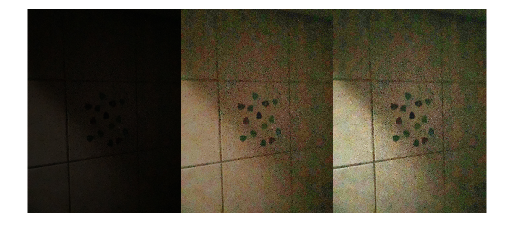

imgObj = imread("picks.jpg");
imgObjB = imlocalbrighten(imgObj);
imgObjR = imreducehaze(imgObj);
montage({imgObj, imgObjB, imgObjR}, "Size", [1 3])